## Variaveis globais

n = 20;
m = 100;
N = 1000;

## (a)

count = 0;
alvos = randi(m,n,N);

for a = 1:N
    if length(alvos(:,a)) == length(unique(alvos(:,a)))
        count = count + 1;
    end
end

probA = count/N

probA = 0.1320

## (b)

alvos = randi(m,n,N);
count = 0;

for a = 1:N    
    if length(alvos(:,a)) == length(unique(alvos(:,a)))
        count = count + 1;
    end
end

probB = 1-count/N

probB = 0.8740

## (c)

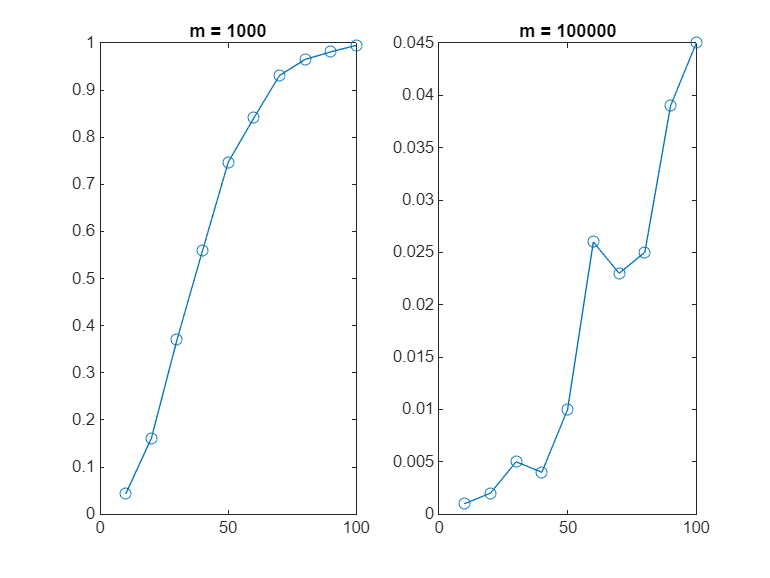

nValores = 10:10:100;
mValores = [1000,100000];
N = 1000;
probC = zeros(length(nValores),length(mValores));

for j = 1:length(mValores)%valor M
    m = mValores(j);
    for i = 1:length(nValores)%valor N
        n = nValores(i);
        contagem = 0;
        alvos = randi(m,n,N);
        for a = 1:N    
            if length(alvos(:,a)) ~= length(unique(alvos(:,a)))
                contagem = contagem + 1;
            end
        end
        probC(i ,j) = contagem/N;
    end
end
figure;

subplot(1, 2, 1);
plot(nValores, probC(:, 1), '-o');
title('m = 1000');

subplot(1, 2, 2);
plot(nValores, probC(:, 2), '-o');
title('m = 100000');

## (d)

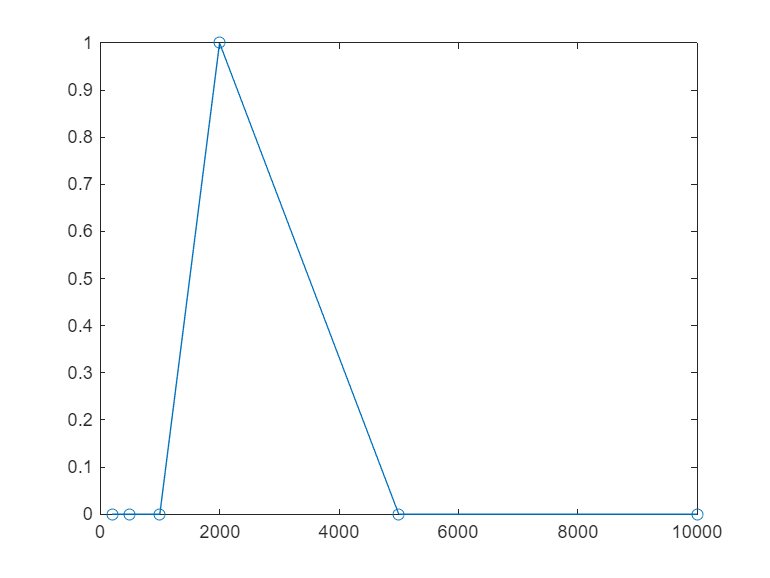

n= 100;
mvalores = [200,500,1000,2000,5000,10000];
N = 1000;

probD = zeros(length(mvalores),1);
for i=1:length(mvalores)
    m = mvalores(i);
    count = 0;
    alvos = randi(m,n,N);
    for j=1:N
        if length(alvos(:,a)) == length (unique(alvos(:,a)))
            count = count + 1;
        end
    end
    probD(i) = count/N;
end

figure;
plot(mvalores,probD, '-o')